# 深度查询

## 初始化

clear;
close all;
clc;
tmp = matlab.desktop.editor.getActive;
index = strfind(tmp.Filename, '\') ;
pathstr = tmp.Filename(1:index(end)-1);
cd(pathstr);
addpath(pathstr);
addpath([pathstr '\function']);

## 读取数据库 地形、声速剖面

etop_dir = 'etopo1.mat';
woa18_dir = 'WOA18_mat';
% 从数据集中加载地形数据和声速剖面数据
[ETOPO, WOA18] = load_data(etop_dir, woa18_dir);
%clear
clear etop_dir
clear woa18_dir
clear index
clear pathstr
clear tmp

## 目标点位参数

%声源点位
coordS.lon = 111; 
coordS.lat = 18.2;
%测线方向及长度
azi = 0;
rmax = 50; 
%计算最远距离接收点经纬度
coordE = [];
[coordS, coordE, rmax, azi] = coord_proc(coordS, coordE, rmax, azi);


## 计算并绘制图像

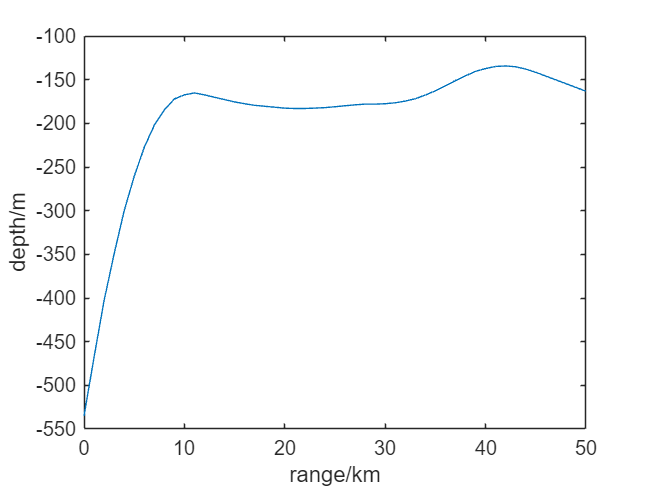

n=ceil(rmax)+1;
lat=linspace(coordS.lat,coordE.lat,n);
lon=linspace(coordS.lon,coordE.lon,n);
r=linspace(0,rmax,n);
depth = get_bathm(ETOPO, lat, lon);
plot(r,-depth)
xlabel('range/km')
ylabel('depth/m')